We begin using the code to generate some graphs that we need in the paper. First of all, we consider single system with p=0.8 and 0.51

p=[0.2,0.8];
p_1=[0.49,0.51];
n=1;

Construct some renewal systems:

R=renewal(p,n);
R_1=renewal(p,n);
R_2=renewal(p,n);
R_3=renewal(p_1,n);
R_4=renewal(p_1,n);

Take these systems into linbreg and assume the regularized function is l1-norm or l2-norm, the stepsize is set for 0.1(default):

solver=linbreg_renew(R,1);
solverl2=linbreg_renew(R_2,2);
solverp1=linbreg_renew(R_3,2);

Also take them into the rm algorithm:

comparer=rm(R_1);
comparerp1=rm(R_4);

Now begin iterating, compare the linbreg with the original algorithm;

solver.iterate;
solverp1.iterate;
comparer.iterate;
comparerp1.iterate;

Plot:

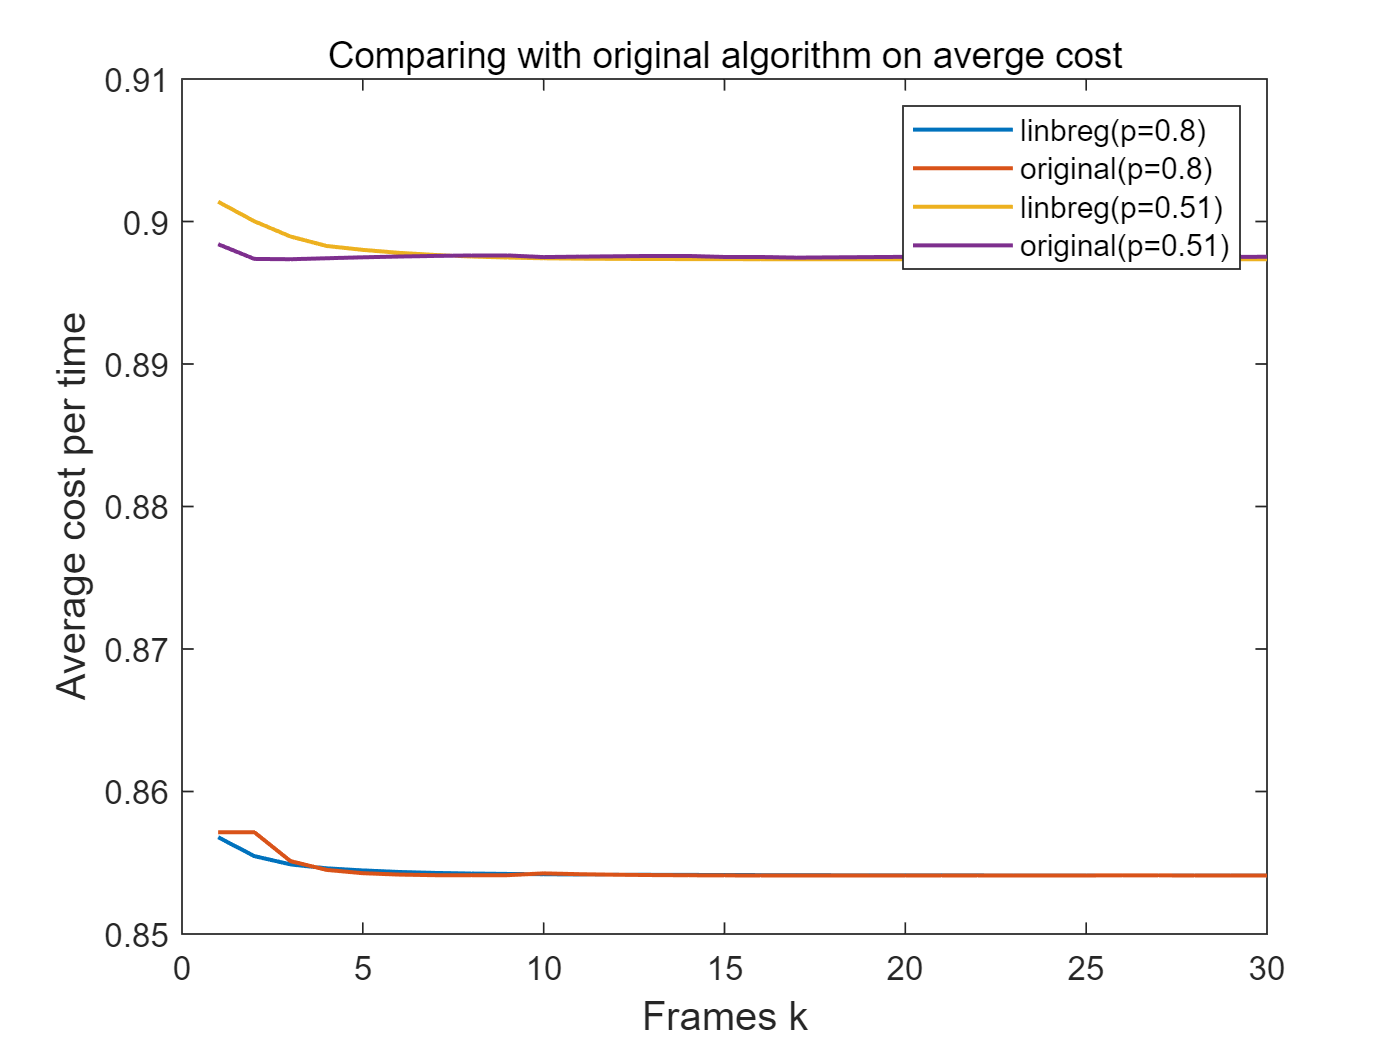

plot(1:30,R.L(1:30),1:30,R_1.L(1:30),1:30,R_3.L(1:30),1:30,R_4.L(1:30),'linewidth',1.2);
hold on;
xlabel('Frames k','Fontsize',12);
ylabel('Average cost per time','Fontsize',12);
legend('linbreg(p=0.8)','original(p=0.8)','linbreg(p=0.51)','original(p=0.51)');
title('Comparing with original algorithm on averge cost')
hold off;

Then let the y-axis be the toal cost/total time:

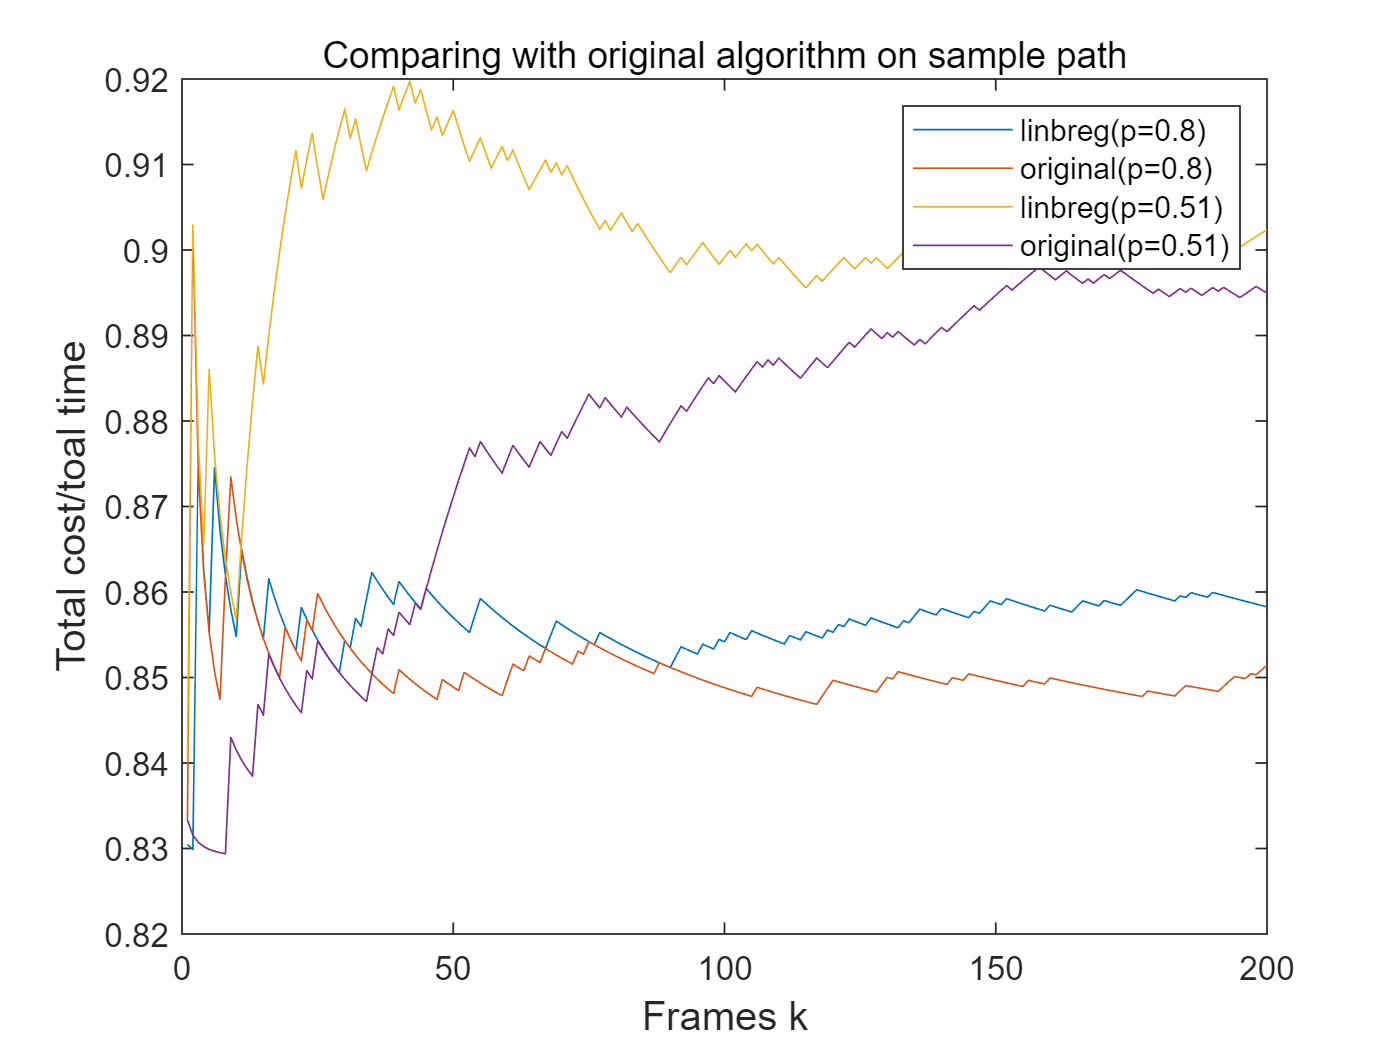

for i=2:200
    R.all_u(1,i)=R.all_u(1,i)+R.all_u(1,i-1);
    R.all_u(2,i)=R.all_u(2,i)+R.all_u(2,i-1);
    R_1.all_u(1,i)=R_1.all_u(1,i)+R_1.all_u(1,i-1);
    R_1.all_u(2,i)=R_1.all_u(2,i)+R_1.all_u(2,i-1);
    R_3.all_u(1,i)=R_3.all_u(1,i)+R_3.all_u(1,i-1);
    R_3.all_u(2,i)=R_3.all_u(2,i)+R_3.all_u(2,i-1);
    R_4.all_u(1,i)=R_4.all_u(1,i)+R_4.all_u(1,i-1);
    R_4.all_u(2,i)=R_4.all_u(2,i)+R_4.all_u(2,i-1);
end
total_ave_R=R.all_u(2,:)./R.all_u(1,:);
total_ave_R_1=R_1.all_u(2,:)./R_1.all_u(1,:);
total_ave_R_4=R_4.all_u(2,:)./R_4.all_u(1,:);
total_ave_R_3=R_3.all_u(2,:)./R_3.all_u(1,:);
plot(1:200,total_ave_R,1:200,total_ave_R_1,1:200,total_ave_R_3,1:200,total_ave_R_4);
hold on;
xlabel('Frames k','Fontsize',12);
ylabel('Total cost/toal time','Fontsize',12);
legend('linbreg(p=0.8)','original(p=0.8)','linbreg(p=0.51)','original(p=0.51)');
title('Comparing with original algorithm on sample path')
hold off;

solver.reinitial;
solverp1.reinitial;
comparer.reinitial;
comparerp1.reinitial;

Compare different regularizers

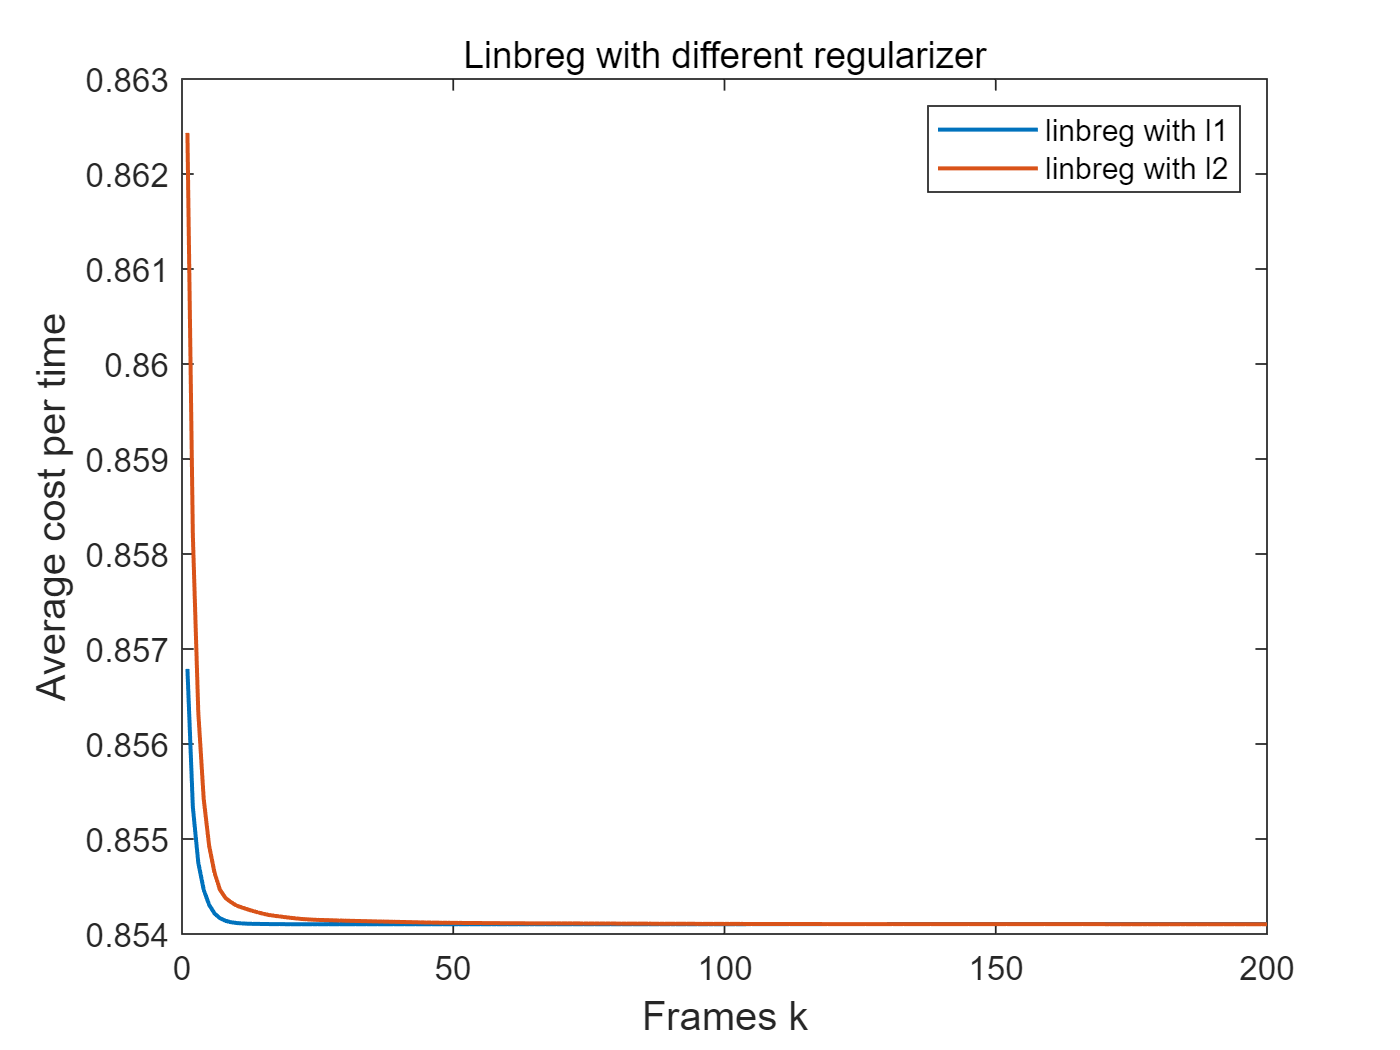

solver.iterate;
solverl2.iterate;
plot(1:200,R.L,1:200,R_2.L,'linewidth',1.2);
hold on;
xlabel('Frames k','Fontsize',12);
ylabel('Average cost per time','Fontsize',12);
legend('linbreg with l1','linbreg with l2');
title('Linbreg with different regularizer')
hold off;

solver.reinitial;
solverl2.reinitial;

Compare different stepsize(0.8, 0.1, 2) in l1 norm:

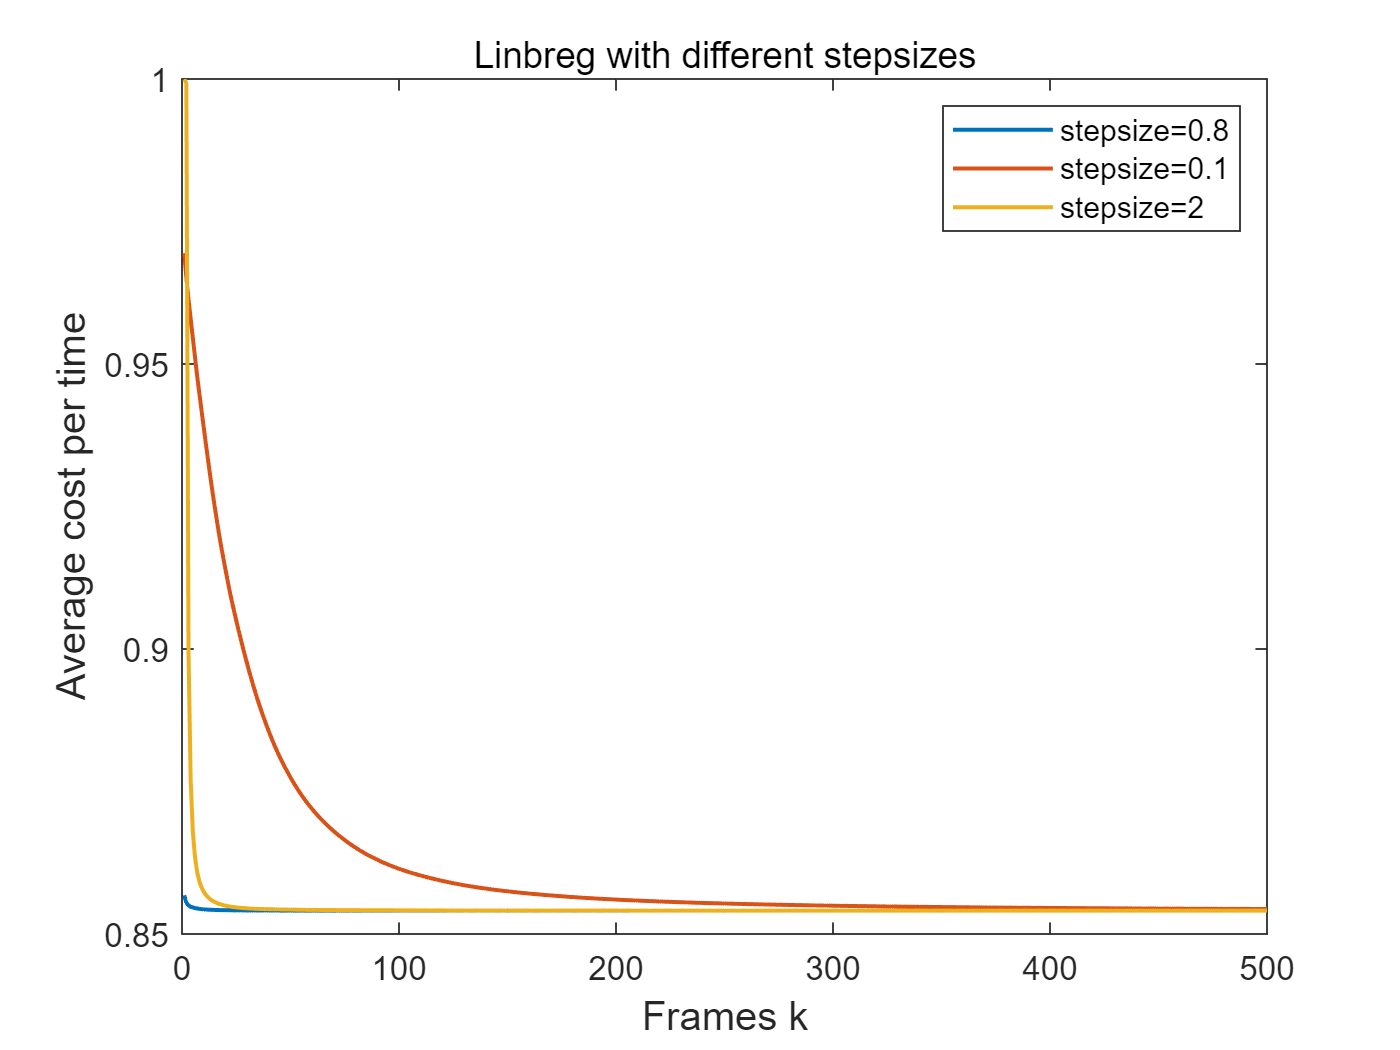

solver.setitemaxiter(500);
solver.iterate;
L08=R.L;
solver.reinitial;
solver.setitemaxiter(500);
solver.setstepsize(0.1);
solver.iterate;
L01=R.L;
solver.reinitial;
solver.setitemaxiter(500);
solver.setstepsize(2);
solver.iterate;
L2=R.L;
plot(1:500,L08,1:500,L01,1:500,L2,'linewidth',1.2);
hold on;
xlabel('Frames k','Fontsize',12);
ylabel('Average cost per time','Fontsize',12);
legend('stepsize=0.8','stepsize=0.1','stepsize=2');
title('Linbreg with different stepsizes');
hold off;

solver.reinitial;

Then we construct the double system which cannot be solved by the original algorithm.

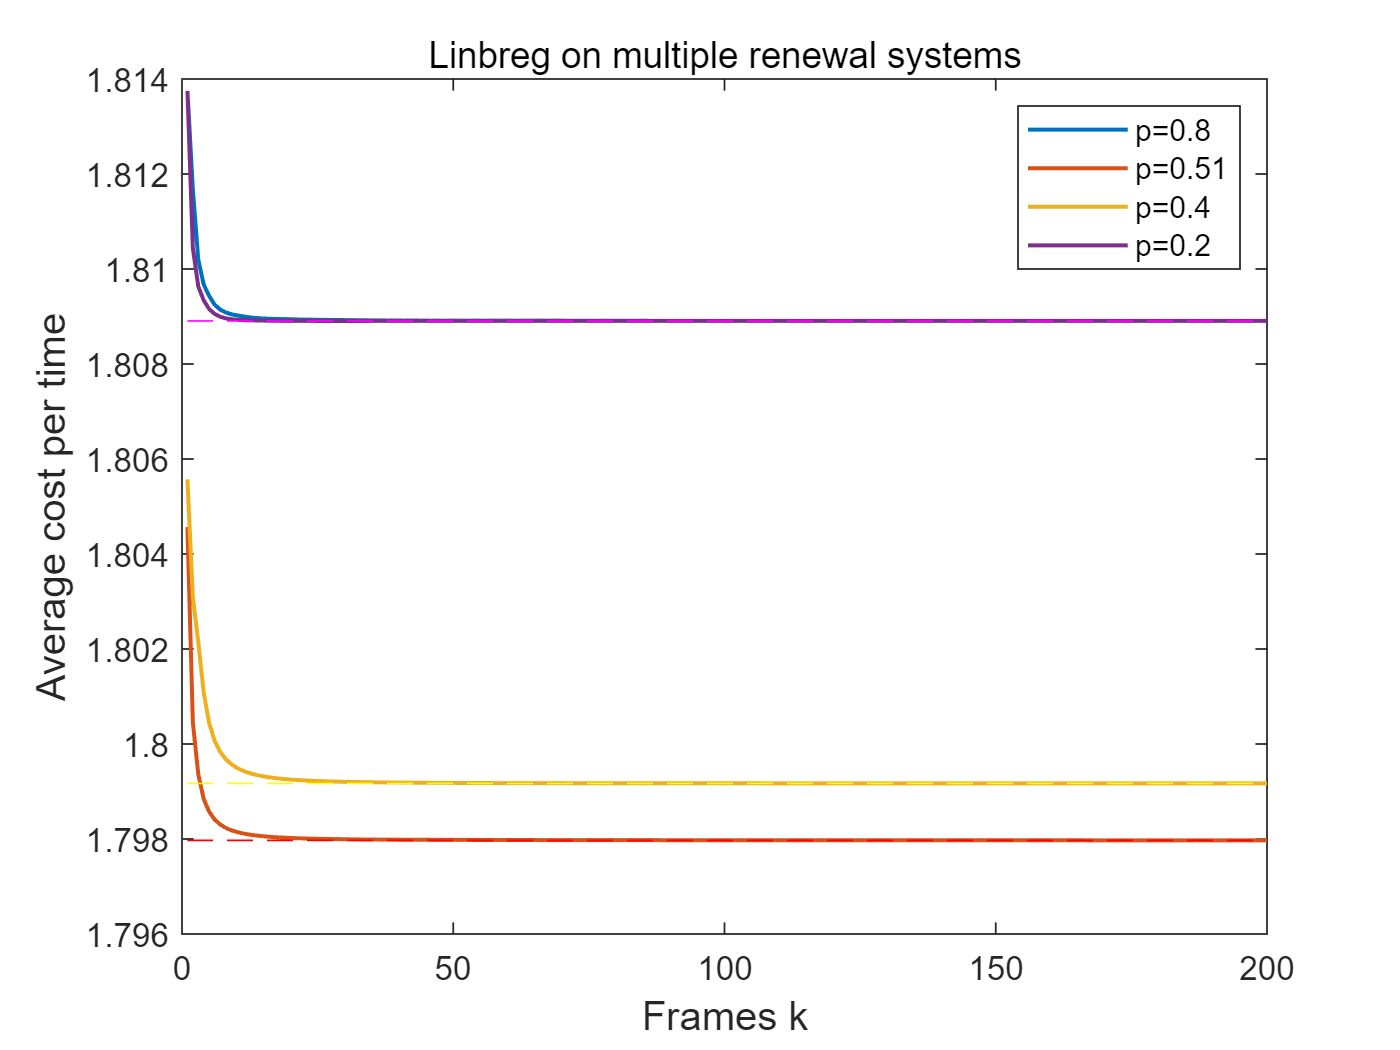

n=2;
p_2=[0.8,0.2];
p_3=[0.6,0.4];
R_5=renewal(p,n);
R_6=renewal(p_1,n);
R_7=renewal(p_2,n);
R_8=renewal(p_3,n);
solver2_08=linbreg_renew(R_5,1);
solver2_51=linbreg_renew(R_6,1);
solver2_02=linbreg_renew(R_7,1);
solver2_04=linbreg_renew(R_8,1);
solver2_08.iterate;
solver2_51.iterate;
solver2_02.iterate;
solver2_04.iterate;
plot(1:200,R_5.L,1:200,R_6.L,1:200,R_8.L,1:200,R_7.L,'linewidth',1.2);
hold on;
line([1,200], [minff(0.8), minff(0.8)], 'Color', 'blue', 'LineStyle', '--');
line([1,200], [minff(0.51), minff(0.51)], 'Color', 'red', 'LineStyle', '--');
line([1,200], [minff(0.4), minff(0.4)], 'Color', 'yellow', 'LineStyle', '--');
line([1,200], [minff(0.2), minff(0.2)], 'Color', 'magenta', 'LineStyle', '--');
xlabel('Frames k','Fontsize',12);
ylabel('Average cost per time','Fontsize',12);
legend('p=0.8','p=0.51','p=0.4','p=0.2');
title('Linbreg on multiple renewal systems');
hold off;

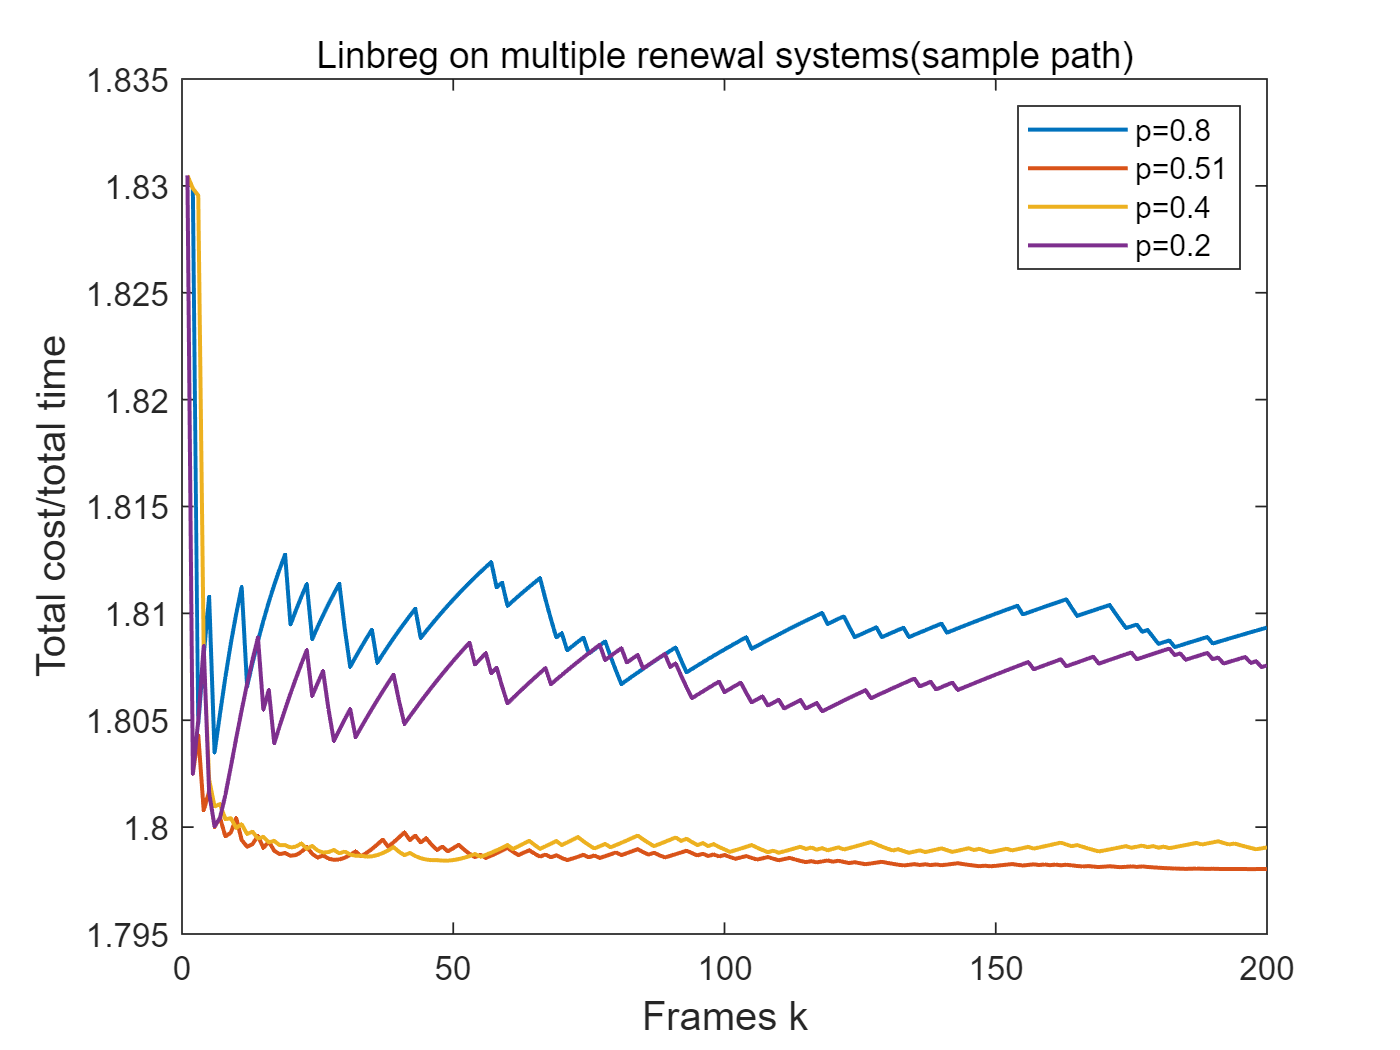

for i=2:200
    R_5.all_u(:,i)=R_5.all_u(:,i)+R_5.all_u(:,i-1);
    R_6.all_u(:,i)=R_6.all_u(:,i)+R_6.all_u(:,i-1);
    R_7.all_u(:,i)=R_7.all_u(:,i)+R_7.all_u(:,i-1);
    R_8.all_u(:,i)=R_8.all_u(:,i)+R_8.all_u(:,i-1);
end
total_R_5=R_5.all_u(2,:)./R_5.all_u(1,:)+R_5.all_u(4,:)./R_5.all_u(3,:);
total_R_6=R_6.all_u(2,:)./R_6.all_u(1,:)+R_6.all_u(4,:)./R_6.all_u(3,:);
total_R_7=R_7.all_u(2,:)./R_7.all_u(1,:)+R_7.all_u(4,:)./R_7.all_u(3,:);
total_R_8=R_8.all_u(2,:)./R_8.all_u(1,:)+R_8.all_u(4,:)./R_8.all_u(3,:);
plot(1:200,total_R_5,1:200,total_R_6,1:200,total_R_8,1:200,total_R_7,'linewidth',1.2);
hold on;
xlabel('Frames k','Fontsize',12);
ylabel('Total cost/total time','Fontsize',12);
legend('p=0.8','p=0.51','p=0.4','p=0.2');
title('Linbreg on multiple renewal systems(sample path)');
hold off;

Now we consider the other example: localize a point with the disturbed distance from sensors. We assume the point 

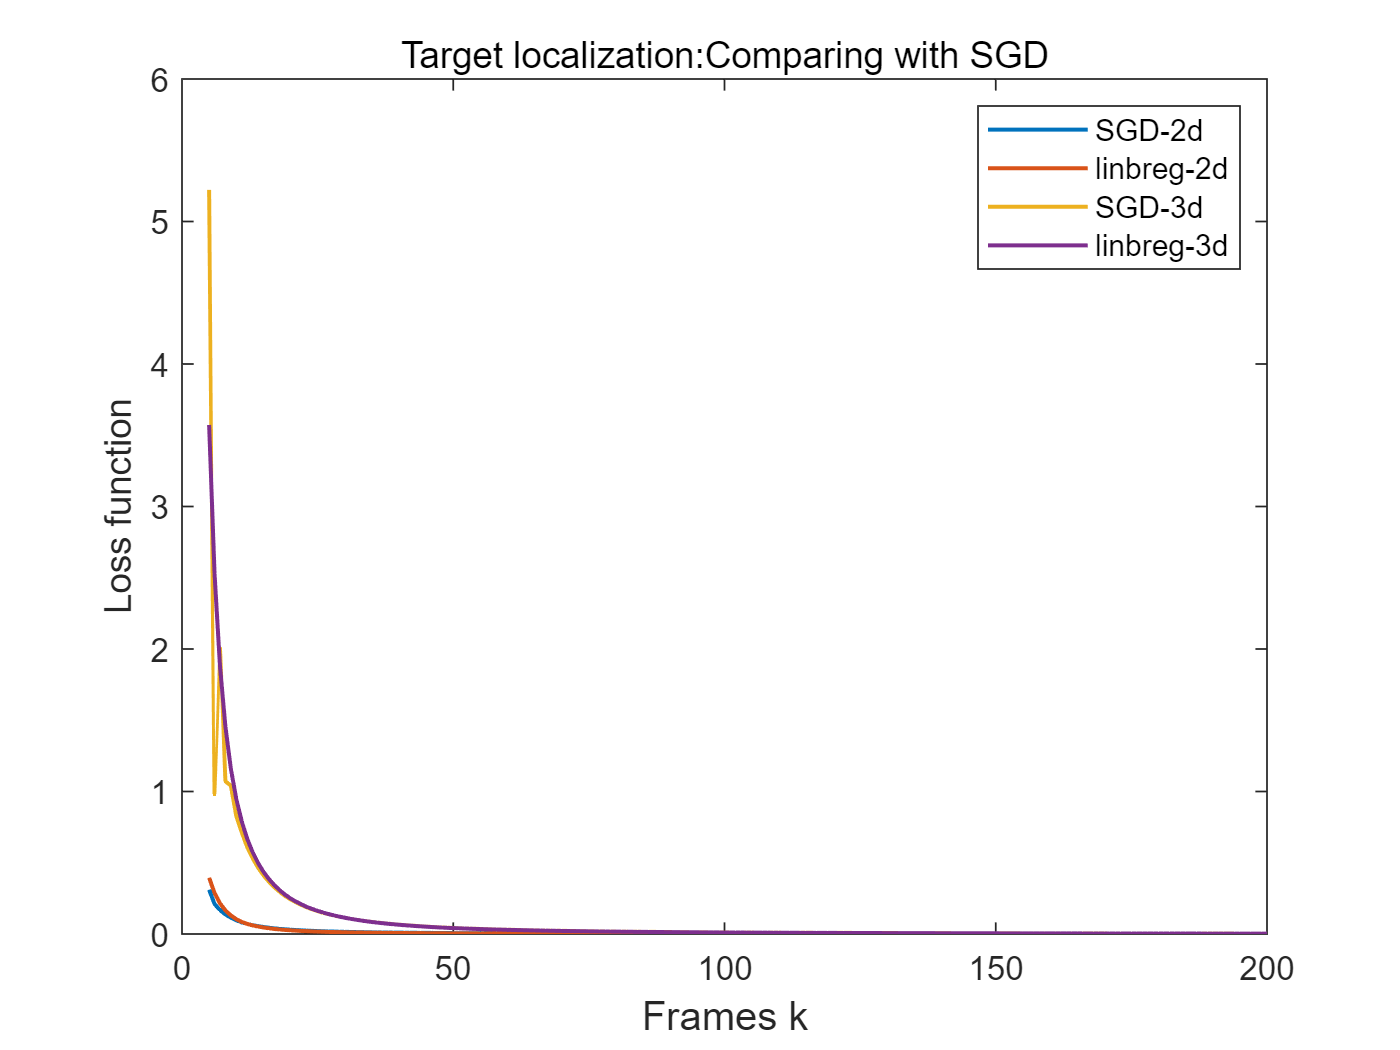

x0=[2,1];
A0=[0.5,0.5;0,0.5;0.5,0];
x1=[4,3,2];
A1=[-1,0,0;0,0,1;0,1,1;1,0,0];
solver_local2d=localize(x0,A0);
solver_local3d=localize(x1,A1);
solver_local2d.iterate;
solver_local3d.iterate;
plot(5:200,solver_local2d.L_sgd(5:200),5:200,solver_local2d.L_lin(5:200),5:200,solver_local3d.L_sgd(5:200),5:200,solver_local3d.L_lin(5:200),'linewidth',1.2);
hold on;
xlabel('Frames k','Fontsize',12);
ylabel('Loss function');
legend('SGD-2d','linbreg-2d','SGD-3d','linbreg-3d');
title('Target localization:Comparing with SGD');
hold off;

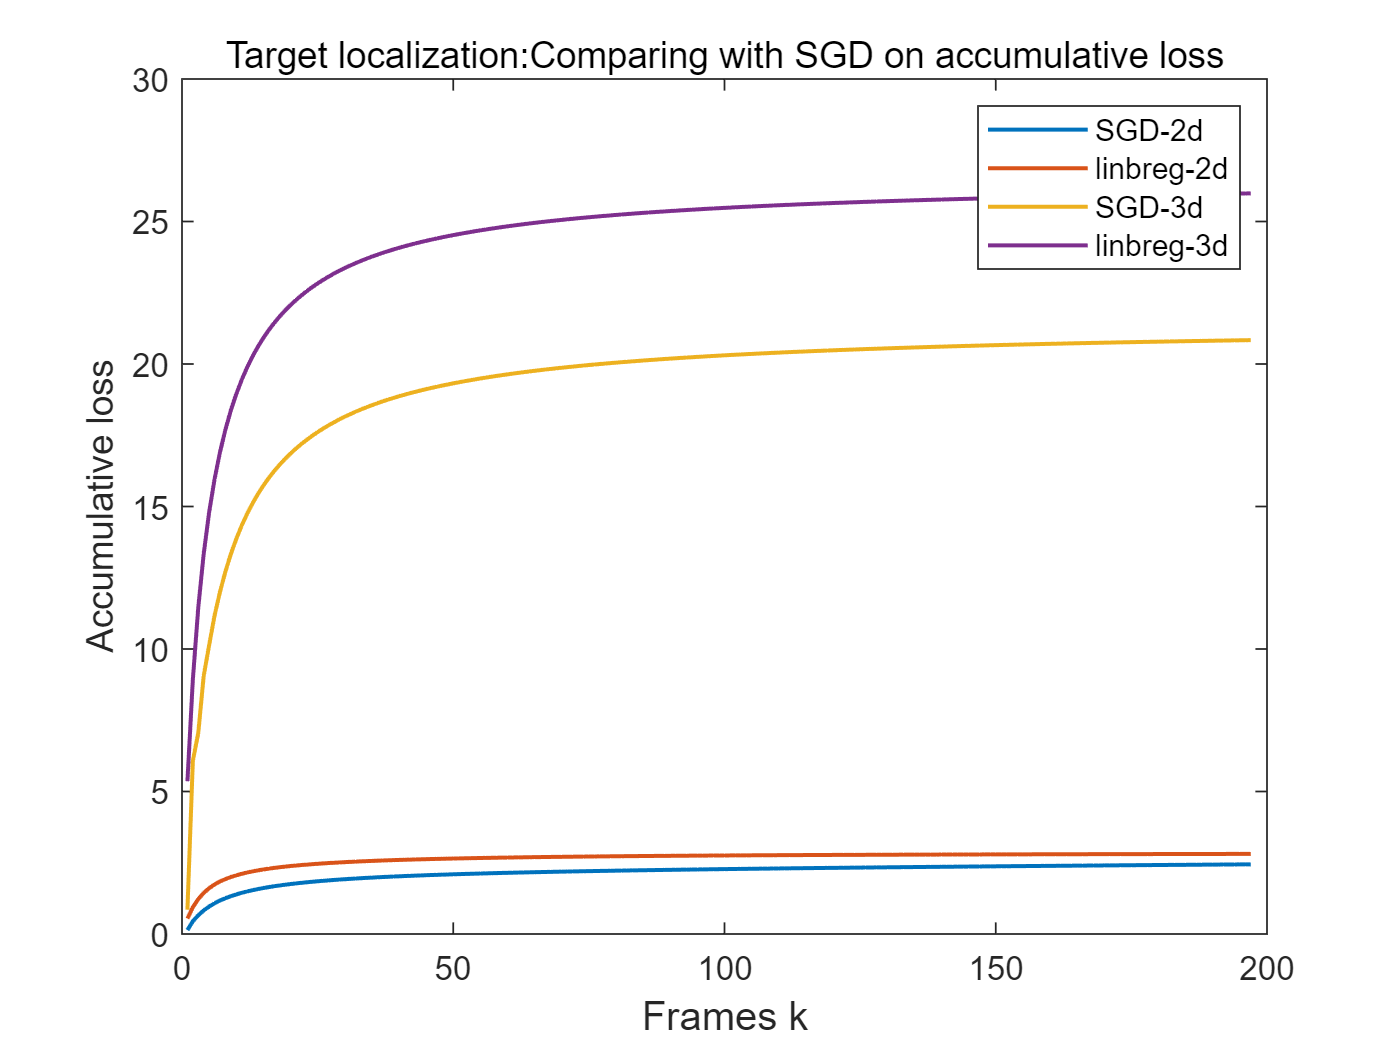

L1=solver_local2d.L_sgd(4);
L2=solver_local2d.L_lin(4);
L3=solver_local3d.L_sgd(4);
L4=solver_local3d.L_lin(4);
for i=5:200
    L1=[L1,L1(i-4)+solver_local2d.L_sgd(i)];
    L2=[L2,L2(i-4)+solver_local2d.L_lin(i)];
    L3=[L3,L3(i-4)+solver_local3d.L_sgd(i)];
    L4=[L4,L4(i-4)+solver_local3d.L_lin(i)];
end
plot(1:197,L1,1:197,L2,1:197,L3,1:197,L4,'linewidth',1.2);
hold on
xlabel('Frames k','Fontsize',12);
ylabel('Accumulative loss');
legend('SGD-2d','linbreg-2d','SGD-3d','linbreg-3d');
title('Target localization:Comparing with SGD on accumulative loss');
hold off;

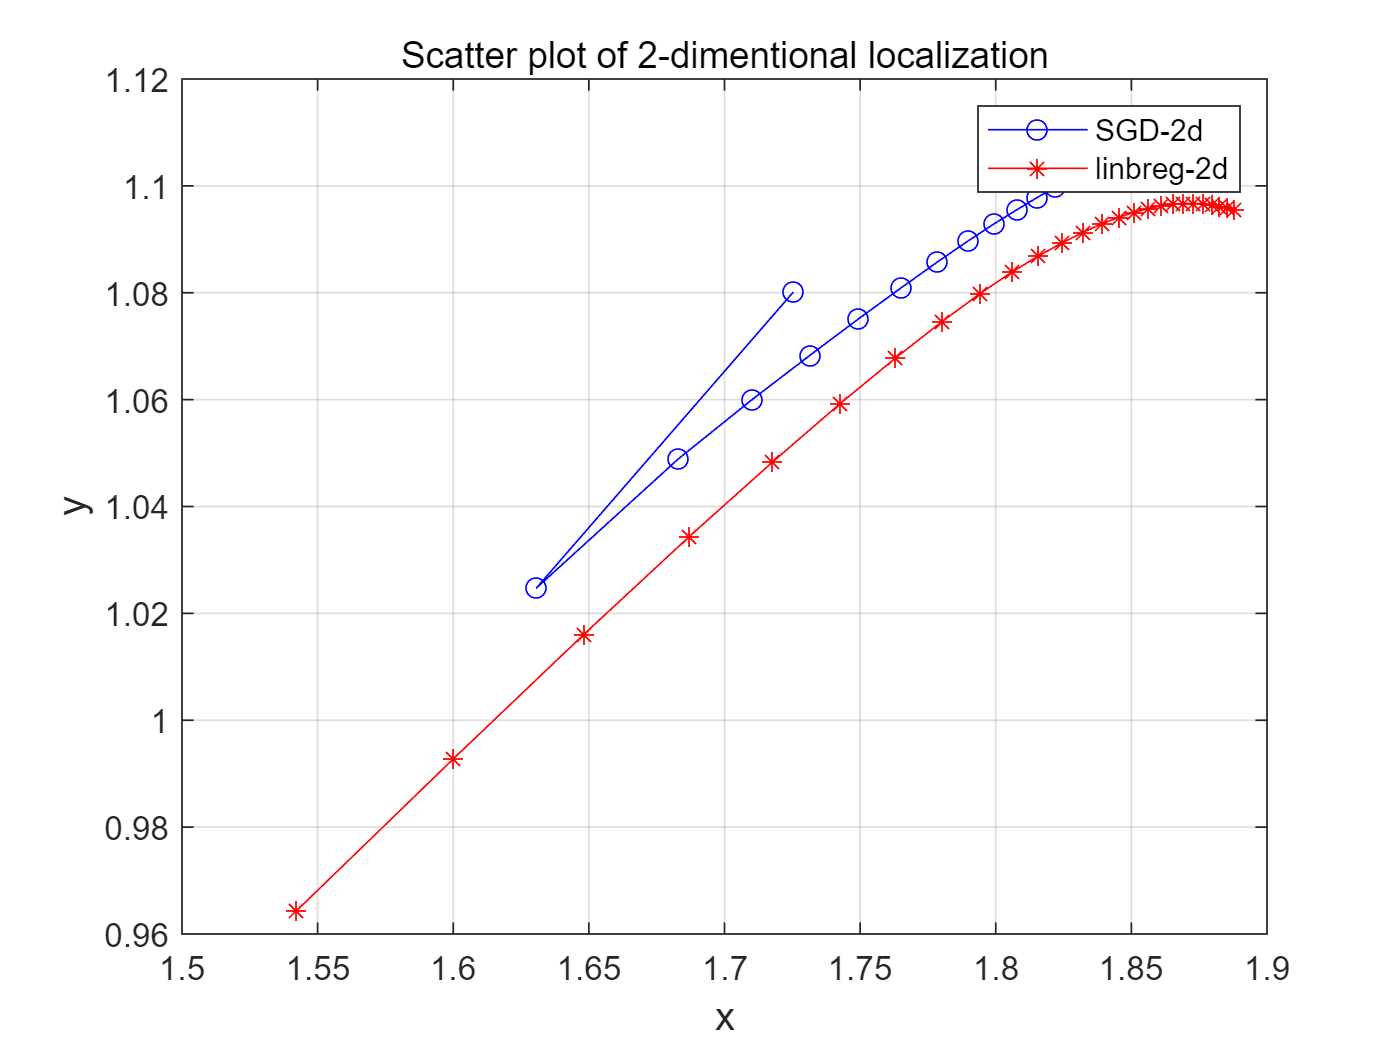

plot(solver_local2d.x_sgd(5:30,1),solver_local2d.x_sgd(5:30,2),'bo-')
hold on;
plot(solver_local2d.x_lin(5:30,1),solver_local2d.x_lin(5:30,2),'r*-')
xlabel('x','Fontsize',12);
ylabel('y','Fontsize',12);
legend('SGD-2d','linbreg-2d')
title('Scatter plot of 2-dimentional localization')
grid on
hold off;